Before attempting to optimize our system, we need to create a model that accurately calculates the position of a body shot off of the Earth. We have created `body_2D_ode45() `to simulate our body in space.

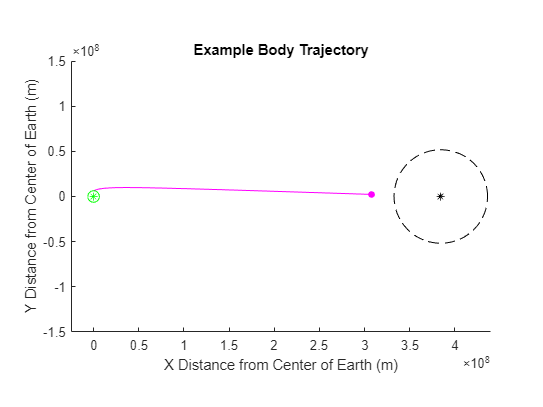

% Example body trajectory
launchAngle = 25;
launchVelocity = 12550;

[T, M] = body_2D_ode45(launchAngle, launchVelocity);

clf;
hold on
plot(M(:,1), M(:,2),'m');

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 50000*1000;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectory')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);

Now that we have a working model, we can input some different values to simulate some different results. 

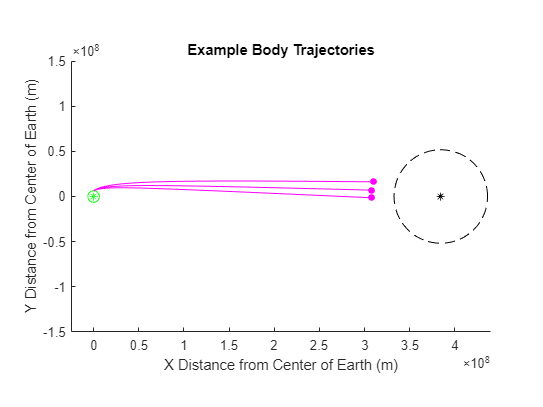

% Body trajectory examples
clf;
hold on

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 50000*1000;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')

launchAngle = 25;
launchVelocity = 12470;
[T, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

launchAngle = 30;
launchVelocity = 11900;
[T, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

launchAngle = 35;
launchVelocity = 11500;
[T, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectories')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);

As you can see, our model stops the simulation when the body gets within 50,000km of the Moon. We can now used this to optimize our model.

% Body trajectory examples
clf;
hold on

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6; % Radius of the Moon
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 75000*1000; % Radius of the Margin of Error
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')

% Parameter Sweep

optimizedVelocity = [];

for launchAngle = 0:1:80
    disp(launchAngle) % Do we still need this display right here, 
                      % or was it just to confirm the code works?
    flag = 0;
    for launchVelocity = 10000:10:16000
        [T, M] = body_2D_ode45(launchAngle, launchVelocity);
        if T(end) ~= 60*60*24*7
            optimizedVelocity = [optimizedVelocity; launchVelocity];
            plot(M(:,1), M(:,2),'m');
            plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)
            flag = 1;
        end
        if flag == 1
            break;
        end
    end 
end

     0

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80



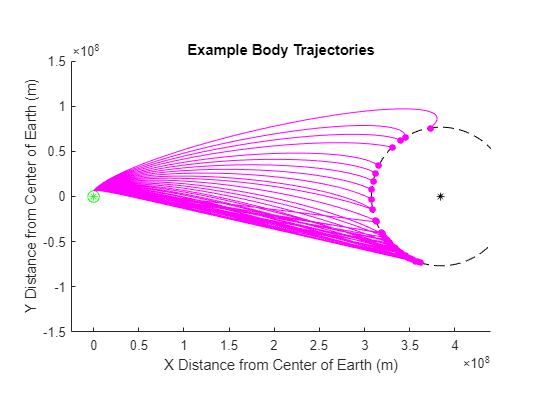


xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectories')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);